# Práctica 2. Filtros FIR e IIR

#### Ejercicio 1. 

**a)** Representa y compara los diagramas de magnitud de la respuesta en frecuencia de filtros FIR de orden 50 usando las siguientes ventanas:

- Triangular

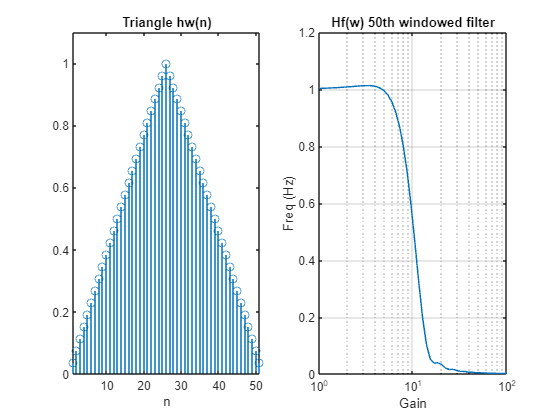

clear all;
close all;

fs=200;%Frecuencia de mnuestreo en Hz
N=50;
fc=10/(fs/2);
hw=triang(N+1);
num_trian=fir1(N,fc,hw);%Numerador de la función de transferencia
den_trian=1; %denominador funcion transferencia
figure (1)
subplot(1,2,1);
stem(hw)
axis([1 51 0 1.1]);
title('Triangle hw(n)')
xlabel('n')
%Pasamos a ver respuesta en frecuencia
subplot(1,2,2)
f=logspace(0,2);
H_trian=freqz(num_trian,den_trian,f,fs);%NOs da la respuesta en frecuencia para las frecuencias f con un muestreo fs
semilogx(f,abs(H_trian)); %Representación usando eje x logarítimico
grid;
xlabel('Gain')
ylabel('Freq (Hz)')
title('Hf(w) 50th windowed filter')

- Hanning

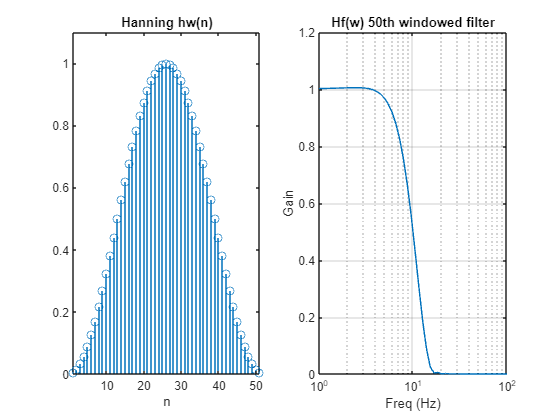

clear all;
close all;

fs=200;%Frecuencia de mnuestreo en Hz
N=50;
fc=10/(fs/2);

hw=hanning(N+1);
num_hann=fir1(N,fc,hw);%Numerador de la función de transferencia
den_hann=1;%Llamamos a la función para hacernos una ventana de hanning 
figure (2)
subplot(1,2,1)
stem(hw);
axis([1 51 0 1.1]);
title('Hanning hw(n)') %n es debido a la discretización
xlabel('n')
%Pasamos a ver respuesta en frecuencia
subplot(1,2,2)
f=logspace(0,2);
H_hann=freqz(num_hann,den_hann,f,fs);%Da la respuesta en frecuencia para las frecuencias f con un muestreo fs
semilogx(f,abs(H_hann)); %Representación usando eje x logarítimico
grid;
ylabel('Gain')
xlabel('Freq (Hz)')
title('Hf(w) 50th windowed filter')

- Blackman 

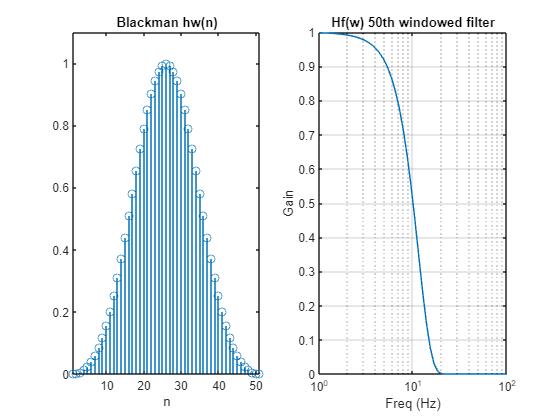

clear all;
close all;

fs=200; %Frecuencia de mnuestreo en Hz
N=50;
fc=10/(fs/2);

hw=blackman(N+1);
num_blk=fir1(N,fc,hw); %Numerador de la función de transferencia
den_blk=1; %Llamamos a la función para hacernos una ventana de hanning 
figure (3)
subplot(1,2,1)
stem(hw);
axis([1 51 0 1.1]);
title('Blackman hw(n)') %n es debido a la discretización
xlabel('n')
%Pasamos a ver respuesta en frecuencia
subplot(1,2,2)
f=logspace(0,2);
H_hann=freqz(num_blk,den_blk,f,fs);%Da la respuesta en frecuencia para las frecuencias f con un muestreo fs
semilogx(f,abs(H_hann)); %Representación usando eje x logarítimico
grid;
ylabel('Gain')
xlabel('Freq (Hz)')
title('Hf(w) 50th windowed filter')

-Chebyshev

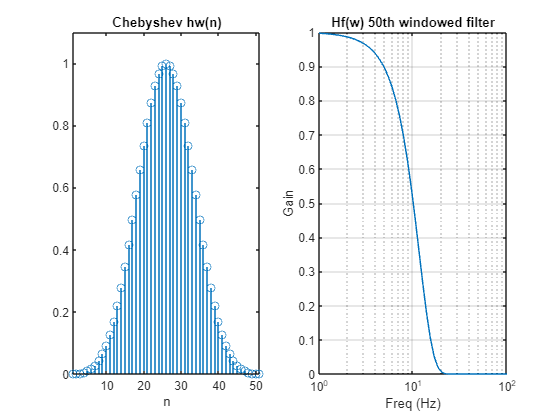

clear all;
close all;

fs=200; %Frecuencia de mnuestreo en Hz
N=50;
fc=10/(fs/2);

hw=chebwin(N+1);
num_che=fir1(N,fc,hw);%Numerador de la función de transferencia
den_che=1;%Llamamos a la función para hacernos una ventana de hanning 
figure (4)
subplot(1,2,1)
stem(hw);
axis([1 51 0 1.1]);
title('Chebyshev hw(n)') %n es debido a la discretización
xlabel('n')
%Pasamos a ver respuesta en frecuencia
subplot(1,2,2)
f=logspace(0,2);
H_che=freqz(num_che,den_che,f,fs);%NOs da la respuesta en frecuencia para las frecuencias f con un muestreo fs
semilogx(f,abs(H_che)); %Representación usando eje x logarítimico
grid;
ylabel('Gain')
xlabel('Freq (Hz)')
title('Hf(w) 50th windowed filter')

**b) **Representa y compara los diagramas de magnitud de la respuesta en frecuencia de los siguientes filtros FIR de orden 50. Emplea las mismas especificaciones en los dos casos. Analiza las gráficas.

- Parks-McLelland 

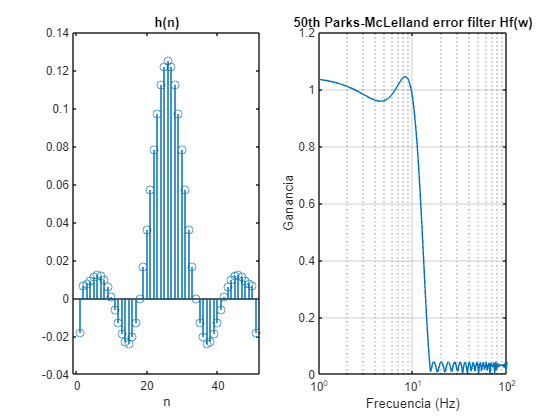

clear all;
close all;

fs=200; %Frecuencia de mnuestreo en Hz
N=50;
fc=10/(fs/2);

F=[0 fc fc+0.05 1];%Frecuencia del diltro paso bajo entre fc y fc+0.05 ha de producirse la caida 
A=[1 1 0 0];

numP=remez(N,F,A); %Genera un filtro optimizando los valores de F y A
denP=1;

figure(1)
subplot(1,2,1)
stem(numP);
axis([1 51 -0.04 0.14]);
title('h(n)') %n es debido a la discretización
xlabel('n')
xlim([-1 52])
%Pasamos a ver respuesta en frecuencia
subplot(1,2,2)
f=logspace(0,2,200);
H_PM=freqz(numP,denP,f,fs);%NOs da la respuesta en frecuencia para las frecuencias f con un muestreo fs
semilogx(f,abs(H_PM)); %Representación usando eje x logarítimico
grid;
ylabel('Ganancia')
xlabel('Frecuencia (Hz)')
title('50th Parks-McLelland error filter Hf(w)')

- Least-Squares Error

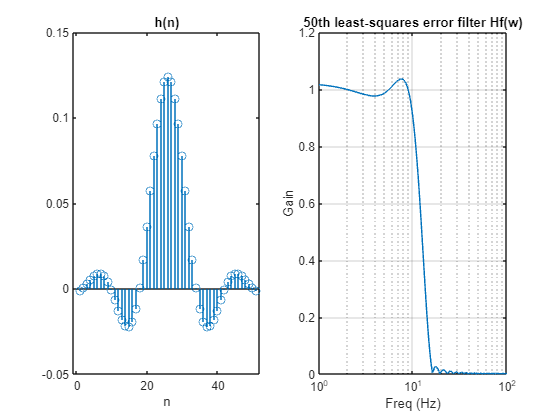

clear all;
close all;

fs=200; %Frecuencia de mnuestreo en Hz
N=50;
fc=10/(fs/2);

F=[0 fc fc+0.05 1]; %Frecuencia del filtro paso bajo entre fc y fc+0.05 ha de producirse la caida 
A=[1 1 0 0];
num_LSE=firls(N,F,A);
den_LSE=1;
figure(1)
subplot(1,2,1)
stem(num_LSE);
axis([1 51 -0.05 0.15]);
title('h(n)') %n es debido a la discretización
xlabel('n')
xlim([-1 52])
%Pasamos a ver respuesta en frecuencia
subplot(1,2,2)
f=logspace(0,2,200);
H_LSE=freqz(num_LSE,den_LSE,f,fs);%NOs da la respuesta en frecuencia para las frecuencias f con un muestreo fs
semilogx(f,abs(H_LSE)); %Representación usando eje x logarítimico
grid;
ylabel('Gain')
xlabel('Freq (Hz)')
title('50th least-squares error filter Hf(w)')